## **Linear Algebra Group Project - Bethany Wu & Alex Stapely**

**Problem 1: Problem Formulation**

Parts (a) & (b)

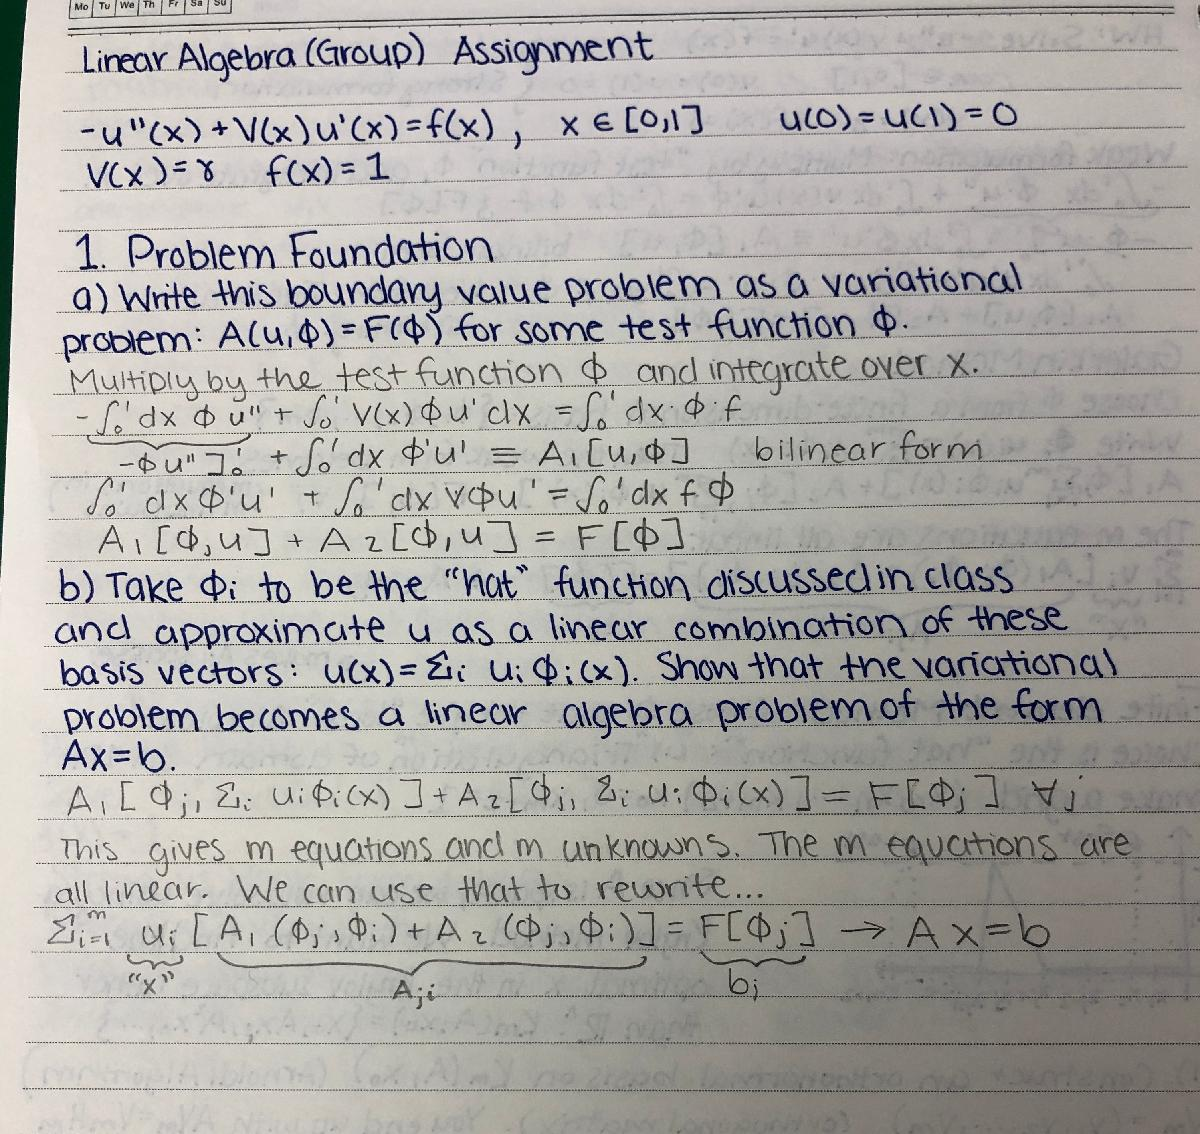

Part (c)

[A1,b1] = BVPtoVar(5,1)

A1 =     0.3333    2.8333         0         0         0
   -3.1667    0.3333    2.8333         0         0
         0   -3.1667    0.3333    2.8333         0
         0         0   -3.1667    0.3333    2.8333
         0         0         0   -3.1667    0.3333


b1 =      6
     6
     6
     6
     6


function [A,b] = BVPtoVar(n,gamma)
    dx = n+1;
    % Forming A1
    side_A1 = ones(n-1,1)*(-1/(dx));
    diag_A1 = ones(n,1)*(2/dx); 
    A1 = diag(side_A1,-1)+diag(diag_A1)+diag(side_A1,1);
    % Forming A2
    side_A2 = ones(n-1,1)*(gamma/2);
    A2 = diag(-side_A2,-1)+diag(side_A2,1);

    A = A1+A2;
    b = ones(n,1)*dx;
end